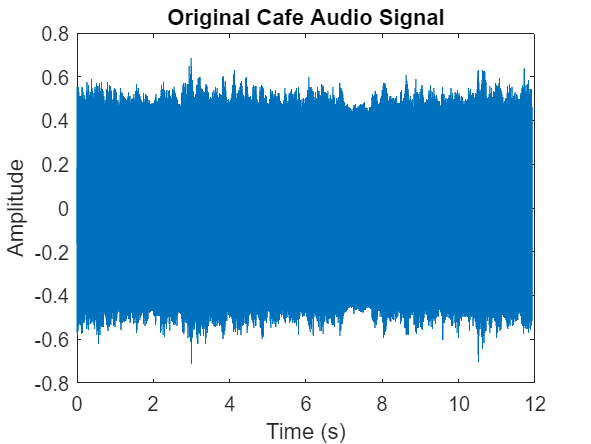

[y, Fs] = audioread("Cafe_with_noise.wav"); % Read the audio file and store the signal in 'y' and sampling rate in 'Fs' 
t = linspace(0, length(y)/Fs, length(y)); % Generate a time vector corresponding to the the sampling rate of the signal
plot(t, y) % Plot the waveform in the time domain
title('Original Cafe Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

sound(y,Fs)

Frequency Domain

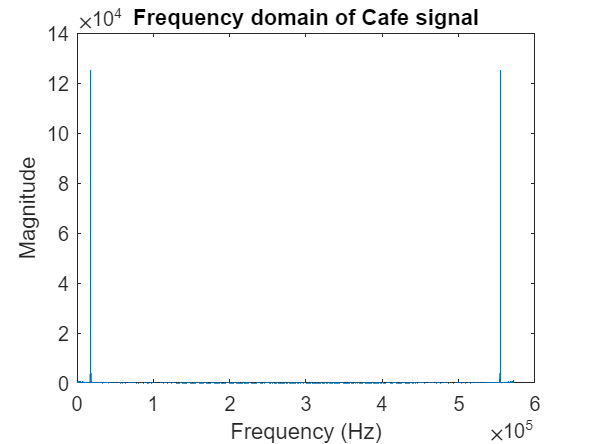

fft_y = fft(y);

plot(abs(fft_y))
title('Frequency domain of Cafe signal')
xlabel('Frequency (Hz)');
ylabel('Magnitude');

Filter the cafe noise to get rid of the blaring high pitched sound

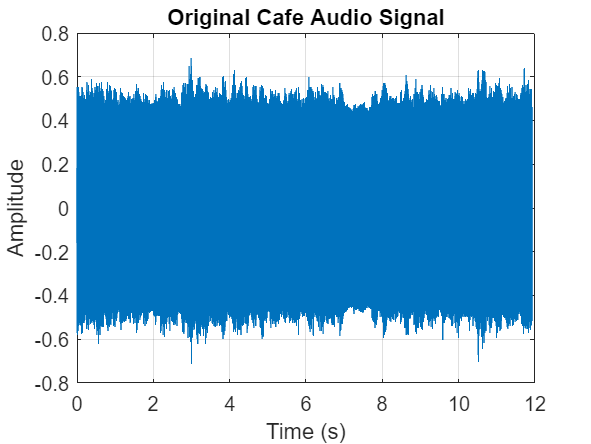

% Step 1: Read the audio file
[y, Fs] = audioread('Cafe_with_noise.wav');  % Read the audio file and sampling rate

% Step 2: Plot the original signal
t = linspace(0, length(y) / Fs, length(y));  % Time vector for the original signal
figure;
plot(t, y);
title('Original Cafe Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

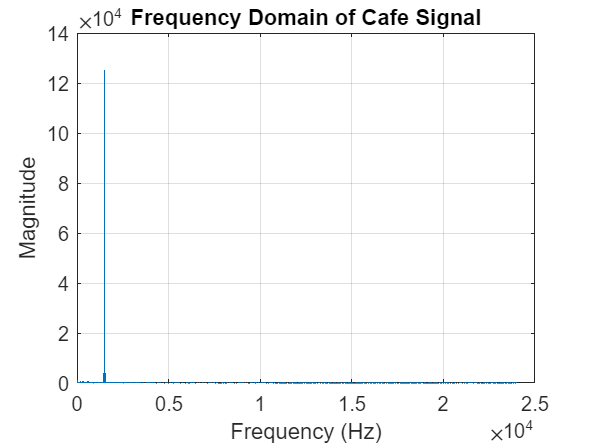


% Frequency domain analysis
fft_y = fft(y);
frequencies = linspace(0, Fs, length(fft_y));  % Frequency vector
figure;
plot(frequencies(1:floor(length(fft_y)/2)), abs(fft_y(1:floor(length(fft_y)/2))));
title('Frequency Domain of Cafe Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

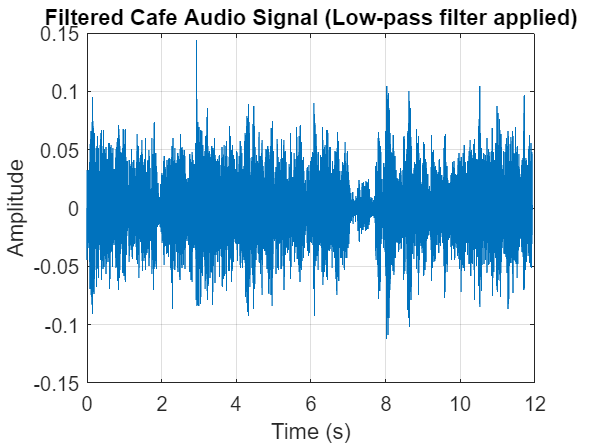


% Step 3: Design a simple FIR low-pass filter
cutoff_freq = 250;  % Cutoff frequency for the low-pass filter (in Hz)

% Normalize the cutoff frequency by Nyquist frequency
nyquist_freq = Fs / 2;  % Nyquist frequency is half of the sampling rate
normalized_cutoff = cutoff_freq / nyquist_freq;

% Filter order (higher order means a steeper cutoff)
filter_order = 100;  % You can adjust this for a sharper filter

% Design an FIR low-pass filter using the 'fir1' function
b = fir1(filter_order, normalized_cutoff, 'low');  % FIR filter coefficients
% The 'fir1' function automatically designs a low-pass filter with a linear phase response

% Step 4: Apply the filter to the audio signal
y_filtered = filter(b, 1, y);  % Apply FIR filter to the audio signal

% Step 5: Plot the filtered signal
figure;
plot(t, y_filtered);
title('Filtered Cafe Audio Signal (Low-pass filter applied)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

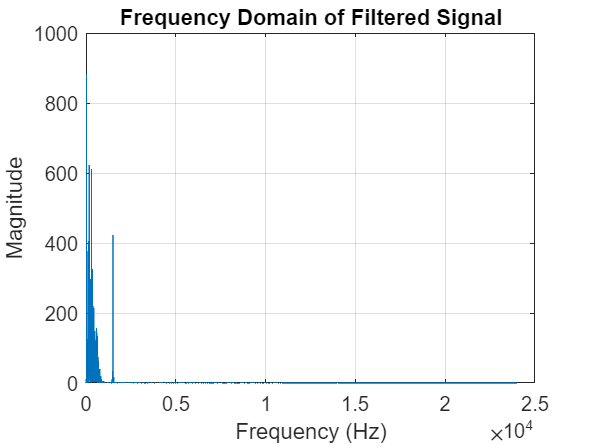


% Frequency domain of the filtered signal
fft_filtered = fft(y_filtered);
figure;
plot(frequencies(1:floor(length(fft_filtered)/2)), abs(fft_filtered(1:floor(length(fft_filtered)/2))));
title('Frequency Domain of Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;


% Step 6: Play the filtered audio
sound(y_filtered, Fs);

% Optional: Save the filtered audio to a new file
audiowrite('Filtered_Cafe_with_noise.wav', y_filtered, Fs);  % Save as a new wav file

Designed another filter to get rid of the pitched sound completely, as from the previous filter, it was only muffeled and not gone. After going through the second filter, the noise was gone and you can hear cafe background voices.

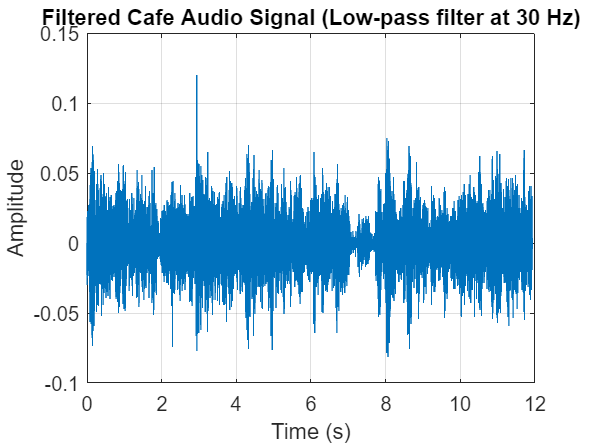

% Step 6: Design another low-pass filter for the already filtered signal (cutoff = 30 Hz)
cutoff_freq_2 = 200;  % New cutoff frequency (in Hz)

% Normalize the cutoff frequency by Nyquist frequency
normalized_cutoff_2 = cutoff_freq_2 / nyquist_freq;

% Filter order (higher order means a steeper cutoff)
filter_order_2 = 100;  % You can adjust this for a sharper filter

% Design the second FIR low-pass filter using the 'fir1' function
b_2 = fir1(filter_order_2, normalized_cutoff_2, 'low');  % FIR filter coefficients

% Step 7: Apply the second filter to the already filtered signal
y_filtered_2 = filter(b_2, 1, y_filtered);  % Apply FIR filter to the already filtered signal

% Step 8: Plot the filtered signal after the second filter (30 Hz cutoff)
figure;
plot(t, y_filtered_2);
title('Filtered Cafe Audio Signal (Low-pass filter at 30 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

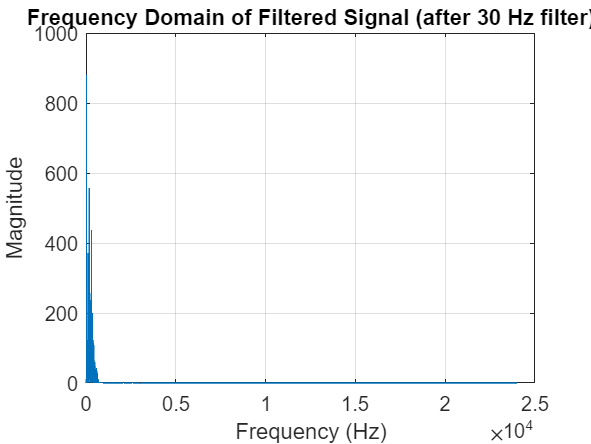


% Frequency domain of the second filtered signal
fft_filtered_2 = fft(y_filtered_2);
figure;
plot(frequencies(1:floor(length(fft_filtered_2)/2)), abs(fft_filtered_2(1:floor(length(fft_filtered_2)/2))));
title('Frequency Domain of Filtered Signal (after 30 Hz filter)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;


% Step 9: Play the final filtered audio
sound(y_filtered_2, Fs);

% Optional: Save the final filtered audio to a new file
audiowrite('Filtered_Cafe_with_noise_30Hz.wav', y_filtered_2, Fs);  % Save as a new wav file
